# Formelsamling

## Kald data ind

clear all
clf
format shortg
data = xlsread("Statestik\Eksamens sæt\22F\Data_M4STI1_2022F.xlsx");
data_size = size(data)


eksempel

## Sandsynlighed - tabel

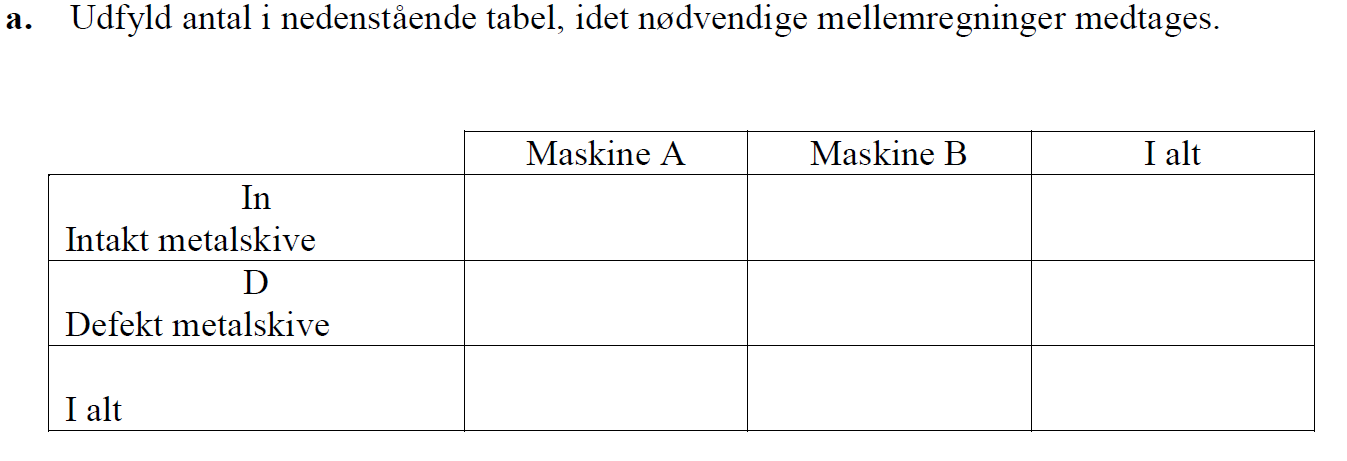

tot = 900
A_tot = 600
A_def = 0.02*A_tot
A_in = A_tot - A_def 
B_tot = 300
B_in = 291
B_def = 9
def_tot = A_def + B_def
int_tot = A_in + B_in
Kol_names = {'Maskine A', ' Maskine B', 'I alt'};
row_names = {'In - intakt metalskive', 'D - defekt metalskive', 'I alt'};
table([A_in; A_def; A_tot], [B_in; B_def; B_tot], [int_tot; def_tot; tot], VariableNames=Kol_names, RowNames=row_names)

## Uafhængighed

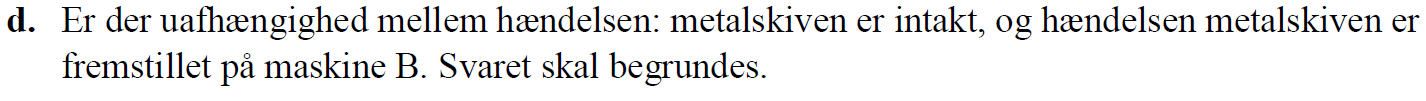

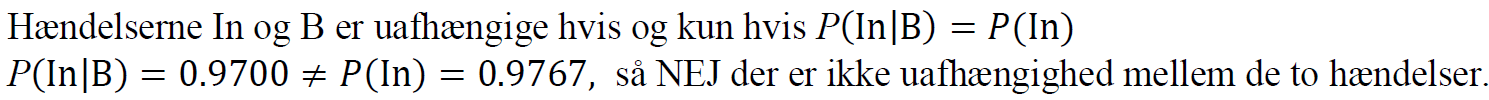

Der skal være lige stor sandsynlighed for at trække en intakt fra den totale pulje som for at trække en intakt fra puljen B - multiplikative lov

P_in_af_B 
P_in
P_in_af_B == P_in

Sandsynligheden er ikke ens og de er derfor ikke uafhængie

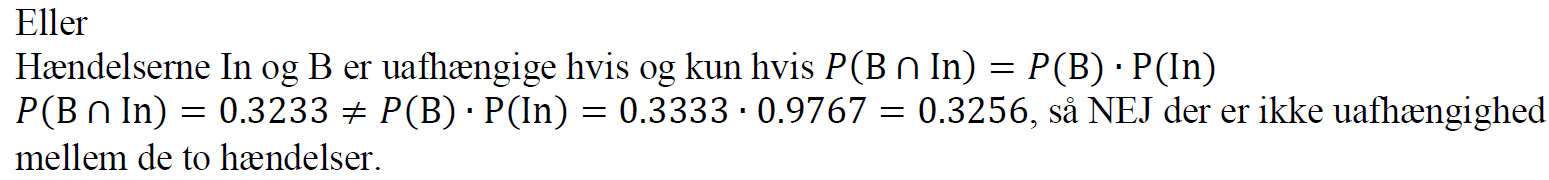

## Sammenligning af to stikprøver

c. Opstil formlen for teststatistikken og beregn dens værdi. Angiv hvilken fordeling den følger.

Den følger en 1. sidet t fordeling  da populationens spredning er ukendt.

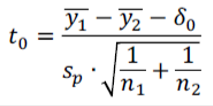

alpha = 0.05;

oprindelig = energi(1:11);
modificeret = energi(12:11+13);
n_op = length(oprindelig)
n_mod = length(modificeret)
df = n_op + n_mod - 2

y_bar_op = mean(oprindelig)
s_op = std(oprindelig)
var_op = var(oprindelig)

y_bar_mod = mean(modificeret)
s_mod = std(modificeret)
var_mod = var(modificeret)

delta_0 = 0 % y_bar_mod - y_bar_op

% Den puljede varians var_p er et vægtet gennemsnit af de to stikprøvers varianser:
s_p = sqrt( ( (n_op -1) * s_op^2 + (n_mod -1) * s_mod^2 ) / (n_op + n_mod - 2) )

%test størrelsen findes
t_0 = (y_bar_op - y_bar_mod - delta_0) / (s_p * sqrt(1/n_op + 1/n_mod))
[h, p ,ci, stats] = ttest2(oprindelig, modificeret, "Alpha", alpha, "Tail", "left")

d. Beregn den kritiske region for testen og konkludér på hypotesetesten.

t_c = tinv(alpha, df)

## ANOVA tests